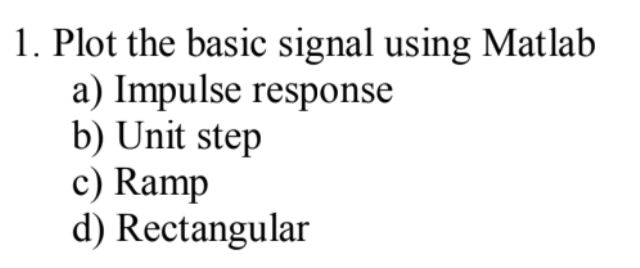

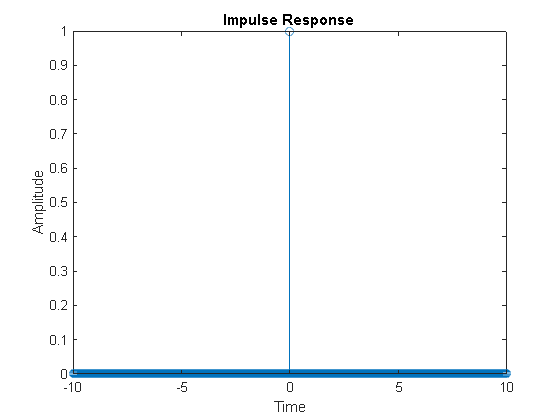

%077BEL028-Nitiz-Khanal
% range of x
x = -10:0.01:10;

% Impulse response
impulse = x == 0;
figure;
stem(x, impulse);
title('Impulse Response ');
xlabel('Time');
ylabel('Amplitude');

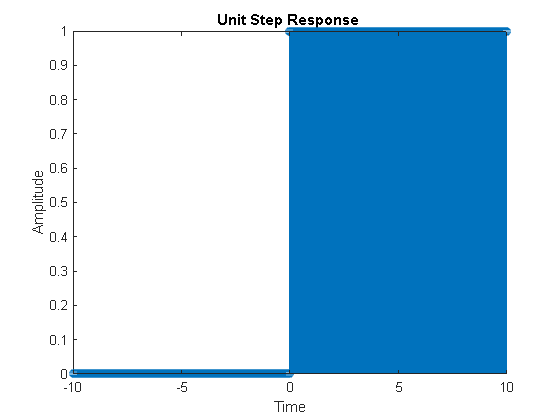

% Unit step
unit_step = x >= 0;

figure;
stem(x, unit_step);
title('Unit Step Response ');
xlabel('Time');
ylabel('Amplitude');

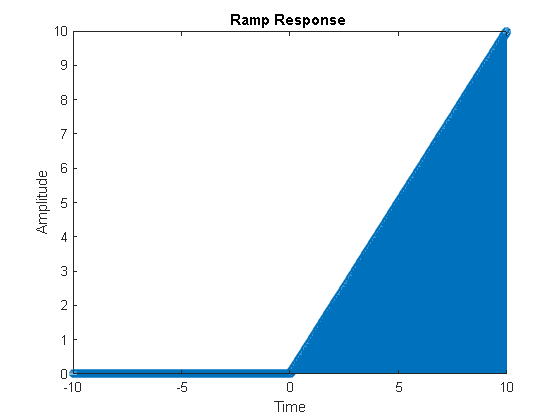

% Ramp
ramp = x .* (x >= 0);

figure;
stem(x, ramp);
title('Ramp Response ');
xlabel('Time');
ylabel('Amplitude');

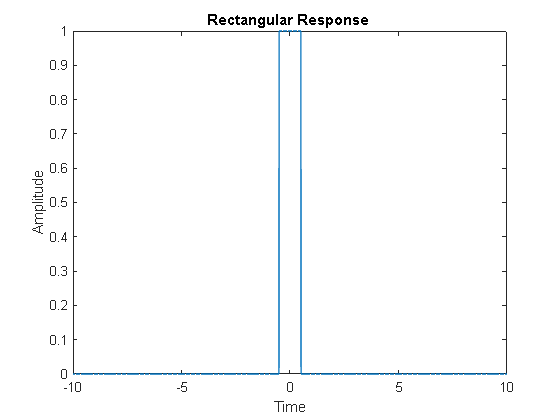


% Rectangular
rectangular = abs(x) <= 0.5;

figure;
plot(x, rectangular);
title('Rectangular Response ');
xlabel('Time');
ylabel('Amplitude');

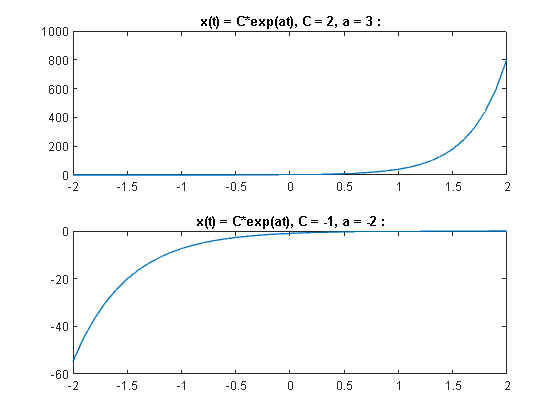

% 2(a)

t = -2:0.1:2;  
f = @(c,a) c*exp(a*t);

% Positive
x1 = f(2,3);
% Negative
x2 = f(-1,-2);

subplot(2,1,1);
plot(t, x1);
title('x(t) = C*exp(at), C = 2, a = 3 :');

subplot(2,1,2);
plot(t, x2);
title('x(t) = C*exp(at), C = -1, a = -2 :');

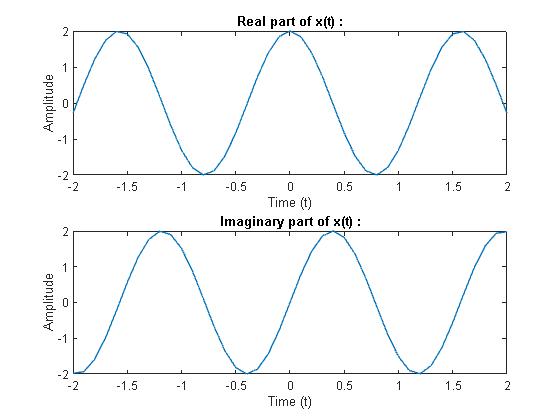

%2(b)

t = -2:0.1:2;

% parameters
C = 2;   
a_imag = 4;  

% complex exponential signal
x = C * exp(1j*a_imag*t);

% Plot the real and imaginary parts separately
figure;
subplot(2,1,1);
plot(t, real(x));
title('Real part of x(t) :');
xlabel('Time (t)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, imag(x));
title('Imaginary part of x(t) :');
xlabel('Time (t)');
ylabel('Amplitude');

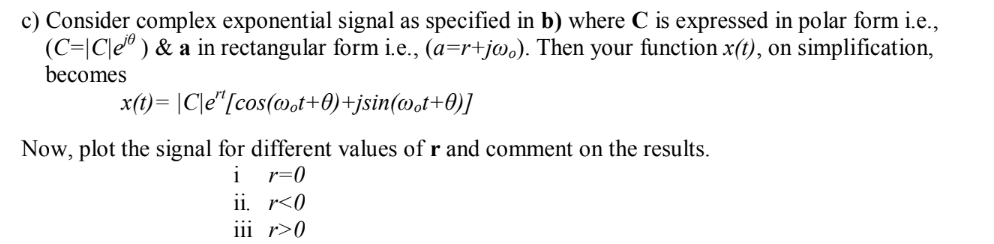

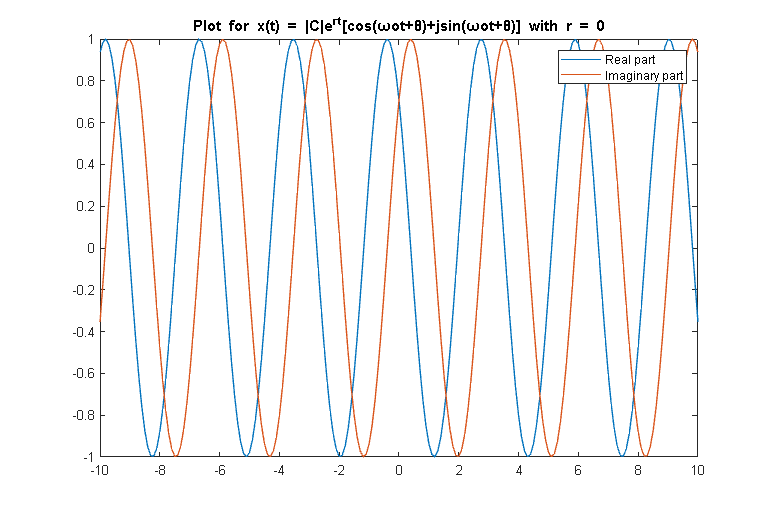

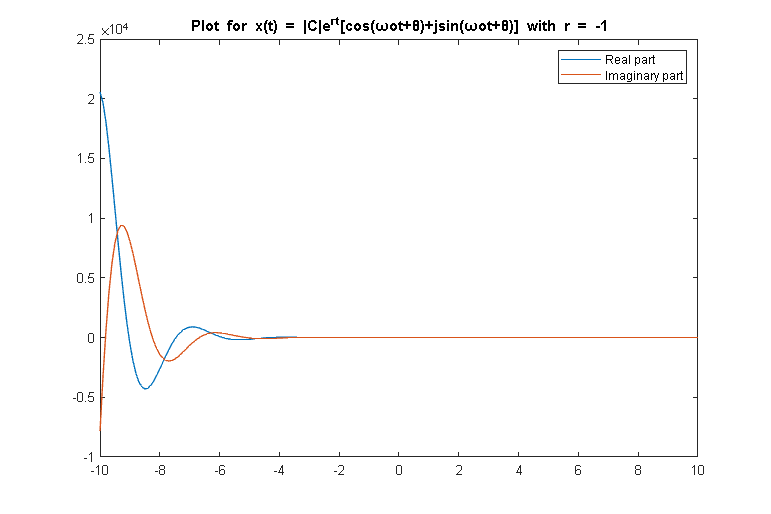

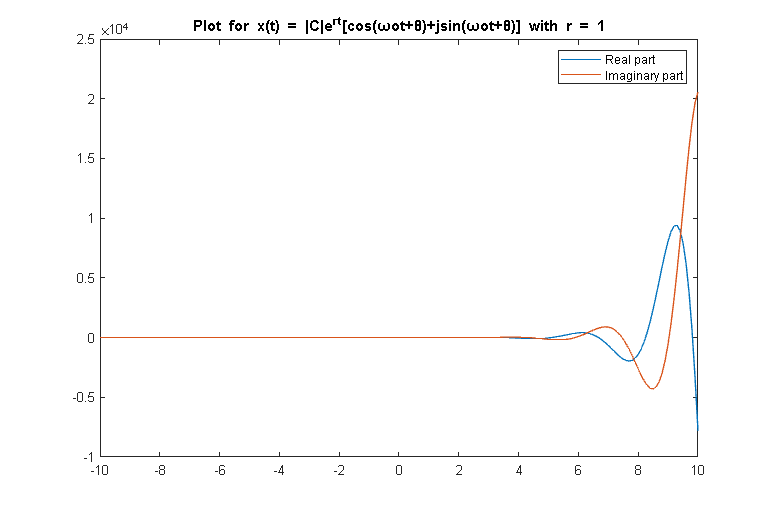

% 2(c) 
t = -10:0.1:10;  

C_abs = 1; 
theta = pi/4; 
r_values = [0, -1, 1]; 
omega = 2; 

for r = r_values
    x = C_abs * exp(r * t) .* (cos(omega * t + theta) + 1i * sin(omega * t + theta));
    figure('Position', [10, 10, 900, 600]);
    plot(t, real(x)); %real part of the signal
    hold on;
    plot(t, imag(x)); %imaginary part of the signal
    legend('Real part', 'Imaginary part');
    title(['Plot for x(t) = |C|e^{rt}[cos(ωot+θ)+jsin(ωot+θ)] with r = ', num2str(r)]);
end

- When `r = 0`, the signal is a pure sinusoid, indicating a constant amplitude over time.

- When `r < 0`, the signal decays over time, indicating a decreasing amplitude.

- When `r > 0`, the signal grows over time, indicating an increasing amplitude.

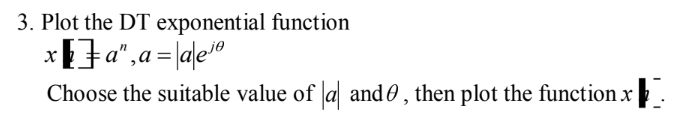

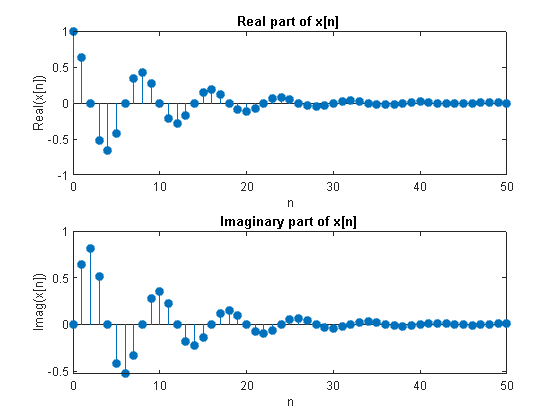

% Define the parameters

n = 0:50; 
a_magnitude = 0.9; 
theta = pi/4; 

a = a_magnitude * exp(1j*theta);

x = a .^ n;

%real and imaginary parts of the function
figure;
subplot(2,1,1);
stem(n, real(x), 'filled');
title('Real part of x[n] ');
xlabel('n');
ylabel('Real(x[n])');

subplot(2,1,2);
stem(n, imag(x), 'filled');
title('Imaginary part of x[n] ');
xlabel('n');
ylabel('Imag(x[n])');

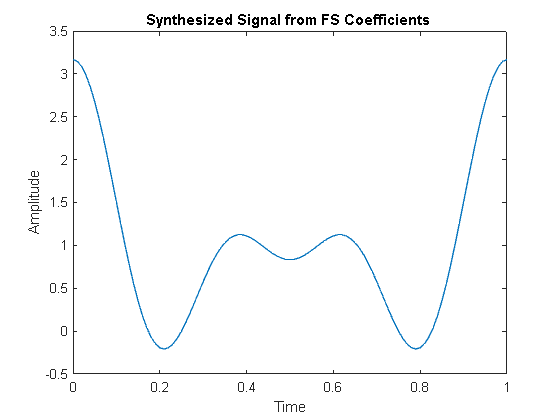

% FS coefficients
C = [1/3, 1/2, 1/4, 1, 1/4, 1/2, 1/3];

t = 0:0.01:1;

x = zeros(size(t));

for k = -3:3
    x = x + C(k+4)*exp(1j*2*pi*k*t);
end

figure;
plot(t, real(x));
title('Synthesized Signal from FS Coefficients ');
xlabel('Time');
ylabel('Amplitude');

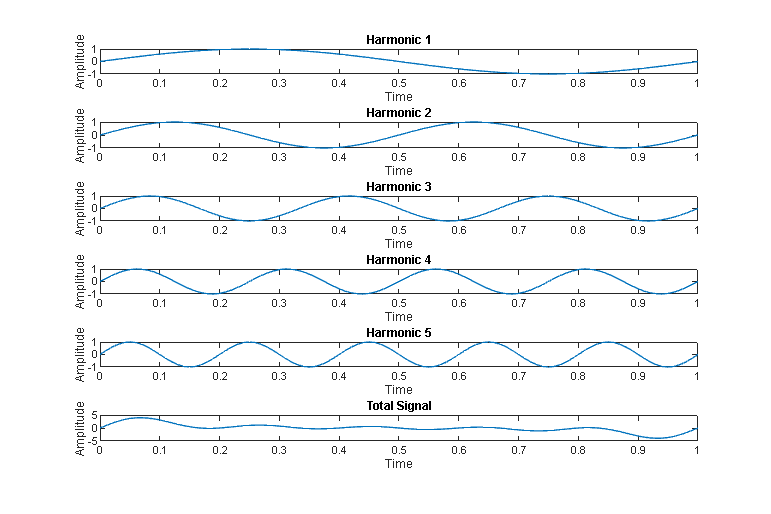

t = 0:0.01:1;

f0 = 1;

total_signal = zeros(size(t));

figure('Position', [10, 10, 900, 600]);
for k = 1:5
    %k-th harmonic signal
    harmonic_signal = sin(2*pi*k*f0*t);
    
    total_signal = total_signal + harmonic_signal;
    
    %harmonic signal
    subplot(6, 1, k);
    plot(t, harmonic_signal);
    title(['Harmonic ', num2str(k)]);
    xlabel('Time');
    ylabel('Amplitude');
end

% Plot the total signal
subplot(6, 1, 6);
plot(t, total_signal);
title('Total Signal');
xlabel('Time');
ylabel('Amplitude');

The first five plots show the fundamental sinusoidal signal and its higher harmonics up to the 5th harmonics. The last plot shows the total signal, which is the sum of all the harmonic signals. As you can see, the total signal has a more complex waveform than any of the individual harmonic signals. This is because the total signal contains all the frequency components of the harmonic signals, resulting in a waveform that is the superposition of all these signals. 